Import fuzzy logic from fuzzy logic designer

fis = readfis('FuzzyLogic.fis');
plotfis(fis);

Example plots of some inputs

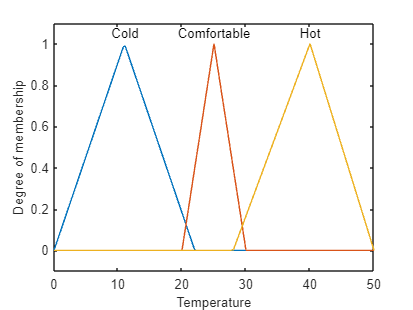

plotmf(fis,"input",1)

plotmf(fis,"output",3)
gensurf(fis)

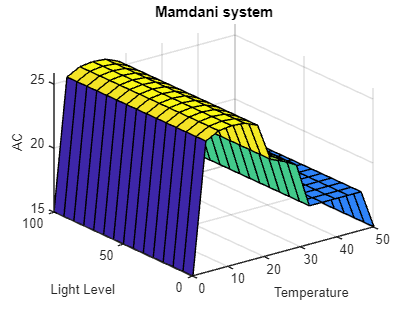

sug_fis = convertToSugeno(fis);
fis_struct = convertToStruct(fis);

gensurf(fis)
title('Mamdani system')

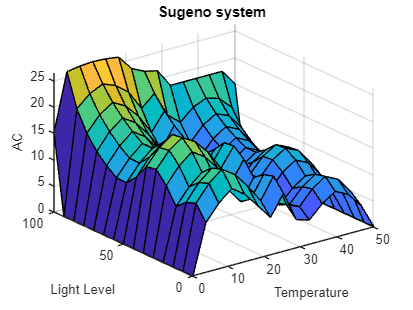

Error using getfis
Membership function indices of input variable 5 must be between 1 and 2, inclusive.

Error in getfis (line 364)
        out.Name = getfis(fis,arg1,arg2,'MF',arg4,'Name');

gensurf(sug_fis)
title('Sugeno system ')

Sample input to defuzzyfication and evaulation

% Define input values
sample_input = [50, 100, 70, 18, 1];

[output,fuzzifiedIn,ruleOut,aggregatedOut,ruleFiring] = evalfis(fis,sample_input);

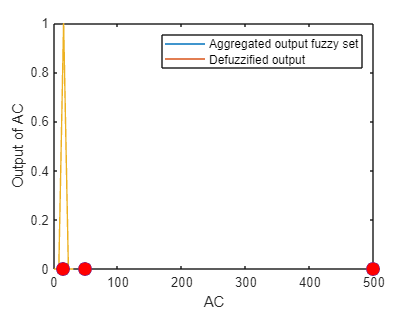


%Defuzzification of output 1
outputRange = linspace(fis.output(1).range(1),fis.output(1).range(2),length(aggregatedOut))'; 
% Plotting
figure;
plot(outputRange, aggregatedOut);
hold on;
plot(output, zeros(size(output)), 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'red');
hold off;
xlabel(fis.Outputs(1).Name);
ylabel('Output of '+fis.Outputs(1).Name);
legend('Aggregated output fuzzy set', 'Defuzzified output');

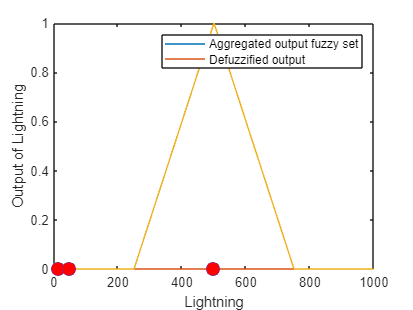


%Defuzzification of output 2
outputRange = linspace(fis.output(2).range(1),fis.output(2).range(2),length(aggregatedOut))'; 
% Plotting
figure;
plot(outputRange, aggregatedOut);
hold on;
plot(output, zeros(size(output)), 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'red');
hold off;
xlabel(fis.Outputs(2).Name);
ylabel('Output of '+fis.Outputs(2).Name);
legend('Aggregated output fuzzy set', 'Defuzzified output');

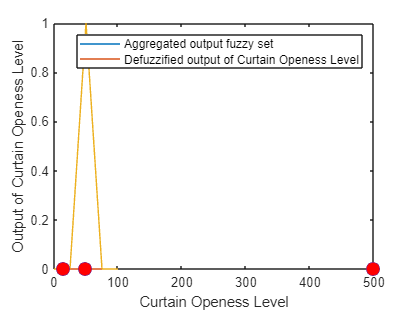



%Defuzzification of output 3
outputRange = linspace(fis.output(3).range(1),fis.output(3).range(2),length(aggregatedOut))'; 
% Plotting
figure;
plot(outputRange, aggregatedOut);
hold on;
plot(output, zeros(size(output)), 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'red');
hold off;
xlabel(fis.Outputs(3).Name);
ylabel('Output of '+fis.Outputs(3).Name);
legend('Aggregated output fuzzy set', 'Defuzzified output of '+ fis.Outputs(3).Name);